nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

%testing git


p_0 = [10, 0, 50];
v_0 = [-3, 0, 0];

origin = [0; 0; 0];
normal2D = table_angle_fzero(p_0([1, 3]), v_0([1, 3]));

h = 0.2727

d = 19.5570

normal = [normal2D(1); 0; normal2D(2)]

normal =    -0.0139
         0
    0.9999



clf; hold on;
plot3(0, 0, 0, 'ro');
plot3(p_0(1), p_0(2), p_0(3), 'gx');

[T, States, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], coeff_restitution, origin, normal, g);
plot3(States(:, 1), States(:, 2), States(:, 3));
view(3);

States(end, 1:3)

ans =   -22.9164         0   -0.3196


States(find(T == endTimes(1)), :)

ans =     0.4174         0    0.0058   -3.0000         0  -31.3031


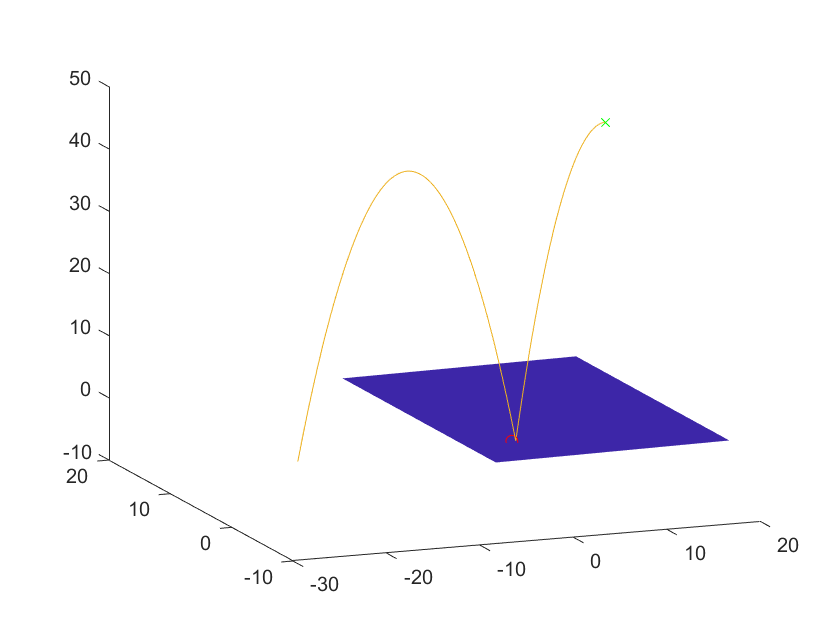


parallel = null(normal.');
p1 = parallel(:, 1);
p2 = parallel(:, 2);

Xbounds = [-5, 20];
Ybounds = [-5, 20];

[a, b] = meshgrid(Xbounds, Ybounds);
X = p1(1) * a + p2(1) * b + origin(1);
Y = p1(2) * a + p2(2) * b + origin(2);
Z = p1(3) * a + p2(3) * b + origin(3);

s = surf(X, Y, Z);
s.FaceColor = 'g';
shading flat